f_fuselage = [0.1:0.01:10];
S_fuselage = [0.5505405115583176, 2.0107744864246584
4.991181261585128, 15.613847853358052
]

S_fuselage =     0.5505    2.0108
    4.9912   15.6138


coef = polyfit(S_fuselage(:,1),S_fuselage(:,2),1)

coef =     3.0633    0.3243


S_fuselageval = polyval(coef,f_fuselage)

S_fuselageval =     0.6306    0.6613    0.6919    0.7225    0.7532    0.7838    0.8144    0.8451    0.8757    0.9063    0.9370    0.9676    0.9982    1.0289    1.0595    1.0901    1.1208    1.1514    1.1820    1.2127    1.2433    1.2739    1.3046    1.3352    1.3658    1.3965    1.4271    1.4577    1.4884    1.5190    1.5496    1.5803    1.6109    1.6415    1.6722    1.7028    1.7334    1.7641    1.7947    1.8253    1.8560    1.8866    1.9172    1.9479    1.9785    2.0091    2.0398    2.0704    2.1010    2.1317


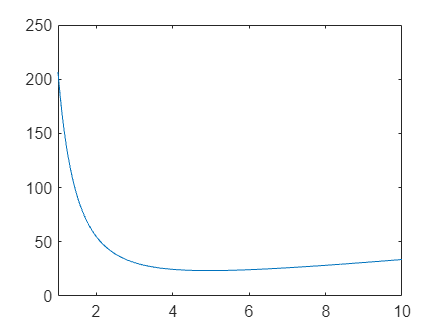

FF_fuselage = (1 + 60./f_fuselage.^3 + f_fuselage./400).*S_fuselageval;
plot(f_fuselage,FF_fuselage)
xlim([1,10])

temp = find(FF_fuselage == min(FF_fuselage));
display(f_fuselage(temp))

    4.9400




f_fuselage = [0.1:0.01:10];
S_fuselage = [4.995797439655218, 13.399457701204602
0.4926340300153703, 1.4346509525973659
]

S_fuselage =     4.9958   13.3995
    0.4926    1.4347


coef = polyfit(S_fuselage(:,1),S_fuselage(:,2),1)

coef =     2.6570    0.1257


plot(f_fuselage,S_fuselageval)
hold on
S_fuselageval = polyval(coef,f_fuselage)

S_fuselageval =     0.3914    0.4180    0.4446    0.4711    0.4977    0.5243    0.5508    0.5774    0.6040    0.6306    0.6571    0.6837    0.7103    0.7368    0.7634    0.7900    0.8165    0.8431    0.8697    0.8963    0.9228    0.9494    0.9760    1.0025    1.0291    1.0557    1.0822    1.1088    1.1354    1.1620    1.1885    1.2151    1.2417    1.2682    1.2948    1.3214    1.3479    1.3745    1.4011    1.4277    1.4542    1.4808    1.5074    1.5339    1.5605    1.5871    1.6136    1.6402    1.6668    1.6934


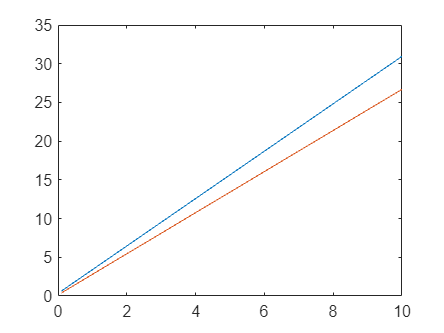

plot(f_fuselage,S_fuselageval)
hold off

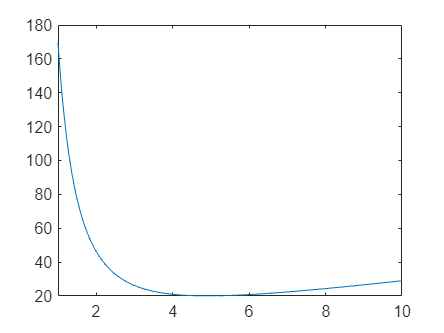

FF_fuselage = (1 + 60./f_fuselage.^3 + f_fuselage./400).*S_fuselageval;
plot(f_fuselage,FF_fuselage)
xlim([1,10])

temp = find(FF_fuselage == min(FF_fuselage));
display(f_fuselage(temp))

    4.9200

